# Lead Controller Design and Experiment

Calculate the gain, poles, and zeros of the controller

% DC Motor Parameters
a = 3.2567;
b = 65.2212;

% Design Requirements
req_Ts = 4 / (0.9*a)

req_Ts = 1.3647

req_OS = 16;

% Calculate Design Point s_d
sigma = 4/req_Ts;
zeta = - log(req_OS/100) / sqrt(pi^2 + log(req_OS/100)^2);
w_n = sigma/zeta;
w = w_n*sqrt(1-zeta^2);
s_d = -sigma + w*1i

s_d = -2.9310 + 5.0247i


% Evaluate Plant TF at s_d
G_p = zpk([], [-a 0], b)

G_p =
 
    65.221
  -----------
  s (s+3.257)
 
Continuous-time zero/pole/gain model.
Model Properties


G_p_sd = evalfr(G_p, s_d);

% Calculate z_PD
phi_ULG = angle(G_p_sd);
phi_PD = -pi - phi_ULG;
z_PD = sigma + w/tan(phi_PD)

z_PD = 12.9879


% Calculate z_c
z_c = 0.7*z_PD

z_c = 9.0915


% Calculate p_c
phi_z = angle(s_d + z_c);
phi_c = phi_PD;
phi_p = phi_z - phi_c;
p_c = sigma + w/tan(phi_p)

p_c = 25.3115


% Evaluate Lead Controller TF at s_d
G_c = zpk(-z_c, -p_c, 1)

G_c =
 
  (s+9.092)
  ---------
  (s+25.31)
 
Continuous-time zero/pole/gain model.
Model Properties


G_c_sd = evalfr(G_c, s_d);

% Evaluate Gain K
K = abs(1/(G_c_sd*G_p_sd))

K = 1.2958

Graph the Root Locus

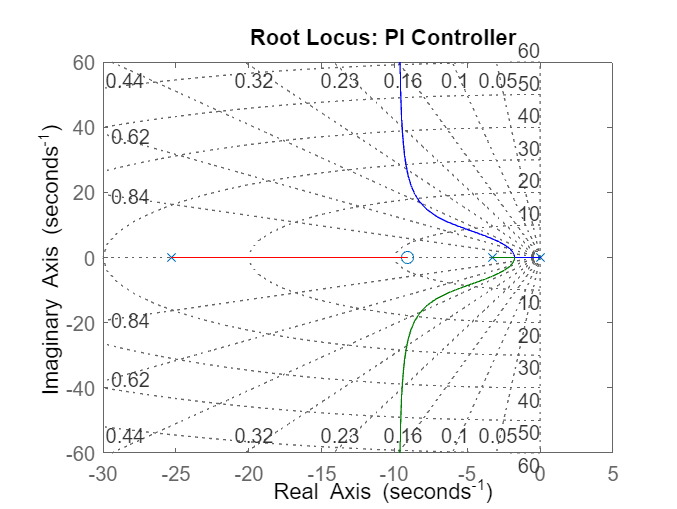

H = zpk([], [], 1); % define the sensor TF
OLTF = G_c*G_p*H; % blocks in cascade

% generate the RL for positive K
rlocus(OLTF); 
title("Root Locus: PI Controller")
sgrid; 

Calculate the Discrete-Time Transfer Function using Tustin's Approximation

Tsamp = 0.01; %s
G_c_z = c2d(G_c,Tsamp,'tustin')

G_c_z =
 
  0.92801 (z-0.913)
  -----------------
     (z-0.7753)
 
Sample time: 0.01 seconds
Discrete-time zero/pole/gain model.
Model Properties


Simulate the response

r = pi; % rad

% run the simulation
out = sim('Lead_Controller_Discrete', 5);

Evaluate the response

F_v_sim = mean(out.Y.Data(end)) % calculate final value

F_v_sim = 3.1416


t = out.Y.Time(out.Y.Data <= 0.98*F_v_sim); % calculate times above -2% final value
% t = out.Y.Time(out.Y.Data >= 1.02*F_v_sim); % calculate times above -2% final value

T_s_sim = t(end)

T_s_sim = 1.3500


u0 = out.u.Data(1) % initial input voltage

u0 = 3.7777


SSE = r - F_v_sim % calculate steady state error

SSE = 1.9469e-06


OS_sim = (findpeaks(out.Y.Data) - F_v_sim) / F_v_sim

OS_sim =     0.2135
    0.0062
    0.0002
    0.0000



peak_input = findpeaks(out.u.Data)

peak_input =     0.0673
    0.0020
    0.0001
    0.0000


Plot the simulated response

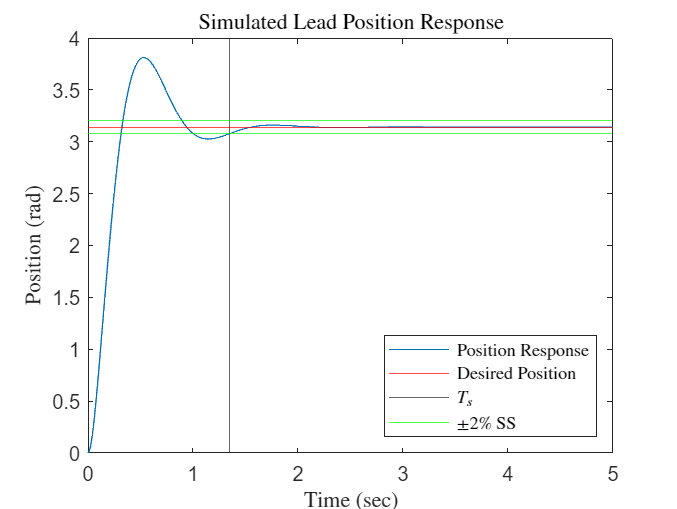

% plot position response
plot(out.Y.Time, out.Y.Data)
yline(r, 'r')
xline(T_s_sim)
yline(F_v_sim * 0.98, 'g')
yline(F_v_sim * 1.02, 'g')
title("Simulated Lead Position Response", 'Interpreter','latex')
xlabel("Time (sec)", 'Interpreter','latex')
ylabel("Position (rad)", 'Interpreter','latex')
legend({"Position Response", "Desired Position", '$T_s$', '$\pm{2\%}$ SS'},'Interpreter','latex', 'Location','southeast') 

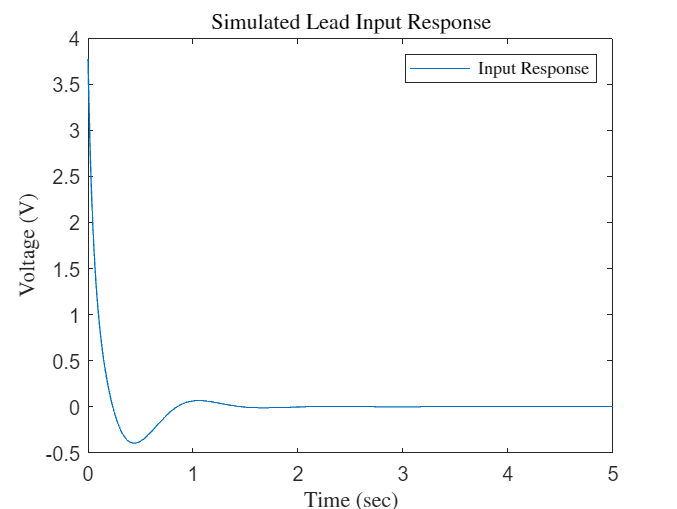


% plot input response
plot(out.u.Time, out.u.Data)
title("Simulated Lead Input Response", 'Interpreter','latex')
xlabel("Time (sec)", 'Interpreter','latex')
ylabel("Voltage (V)", 'Interpreter','latex')
legend('Input Response','Interpreter','latex', 'Location','northeast') 

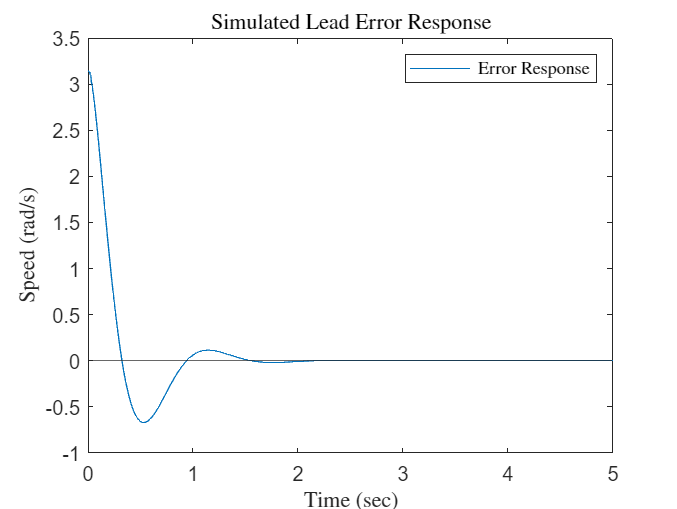


% plot error response
plot(out.e.Time, out.e.Data)
yline(0)
title("Simulated Lead Error Response", 'Interpreter','latex')
xlabel("Time (sec)", 'Interpreter','latex')
ylabel("Speed (rad/s)", 'Interpreter','latex')
legend('Error Response','Interpreter','latex', 'Location','northeast') 

Open serial port.

clear s % closes ports already open
s = serialport('COM11',9600) % Check COM#11

s =   Serialport with properties:

                 Port: "COM11"
             BaudRate: 9600
    NumBytesAvailable: 0

  Show all properties, functions


Read serial port values and parse data into lists. 

values = 176;
t = zeros(1, values);
pos = zeros(1, values);
spd = zeros(1, values);
inpt = zeros(1, values);
error = zeros(1, values);

% loop through all 
for n = 1:values
    msg = s.readline();
    items = split(msg, ',');
    vals = arrayfun(@str2num, items);
    t(n) = vals(1);
    pos(n) = vals(2);
    spd(n) = vals(3);
    inpt(n) = vals(4);
    error(n) = vals(5);
end

% save Lead_3_12032024.mat t pos spd inpt error

Load Trial Data

load Lead_4_12032024.mat

Evaluate the response

u0 = inpt(1)

u0 = 3.7778

F_v = mean(pos(end-10:end)) % steady state speed

F_v = 2.8225

SSE = F_v - r

SSE = -0.3191

i = find(pos <= 0.98 * F_v);
T_s = t(i(end))

T_s = 0.3100

OS = (max(pos)-F_v)/F_v

OS = 5.4349e-04

Plot speed, angle and input voltage with respect to time. 

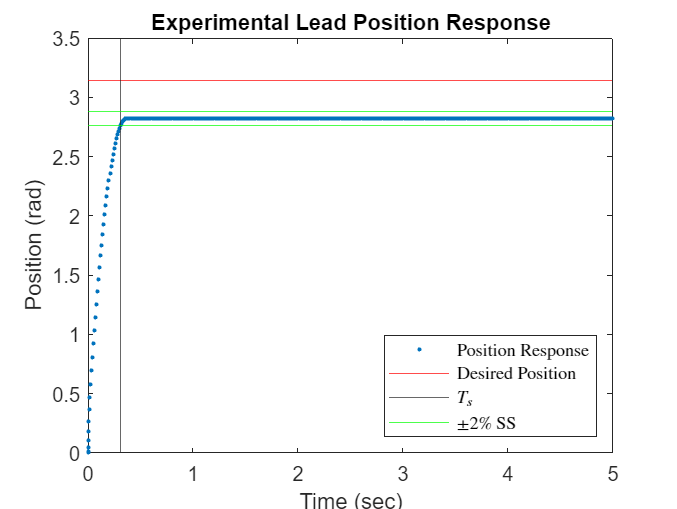

% plot position
plot(t, pos, '.')
yline(r, 'r')
xline(T_s)
yline(F_v * 0.98, 'g')
yline(F_v * 1.02, 'g')
title("Experimental Lead Position Response")
xlabel("Time (sec)")
ylabel("Position (rad)")
legend({"Position Response", "Desired Position", '$T_s$', '$\pm{2\%}$ SS'},'Interpreter','latex', 'Location','southeast') 

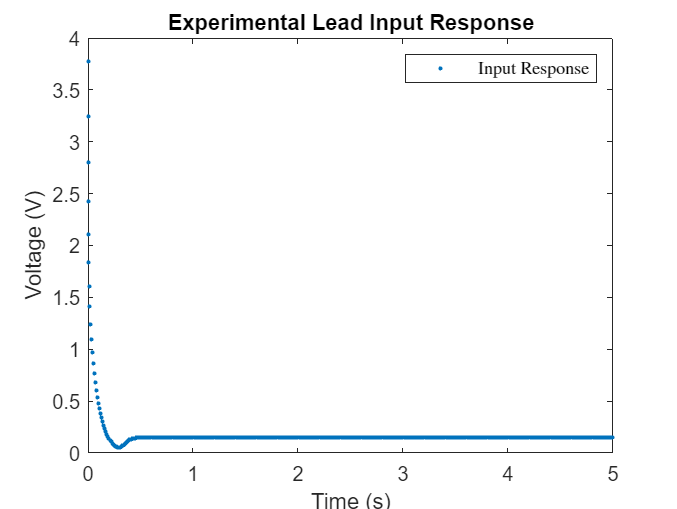


% plot input voltage
plot(t, inpt, '.')
title("Experimental Lead Input Response")
xlabel("Time (s)")
ylabel("Voltage (V)")
legend("Input Response", 'Interpreter','latex', 'Location','northeast') 

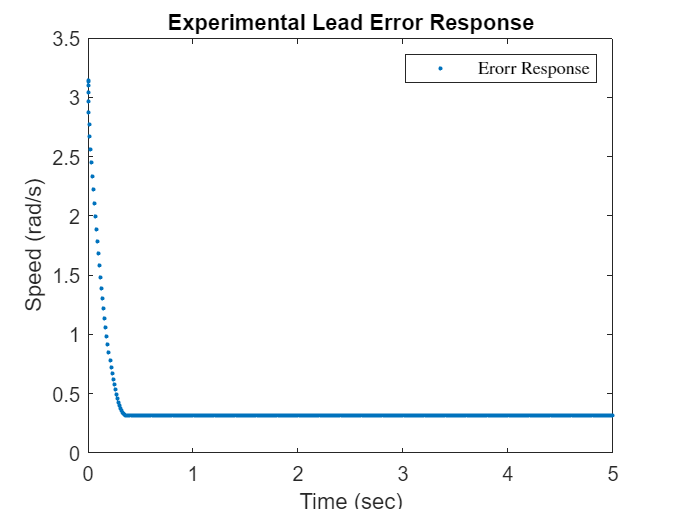


% plot error response
plot(t, error, '.')
yline(0)
title("Experimental Lead Error Response")
xlabel("Time (sec)")
ylabel("Speed (rad/s)")
legend("Erorr Response", 'Interpreter','latex', 'Location','northeast') 

Plot both simulated and experimental position, angle and input voltage with respect to time.

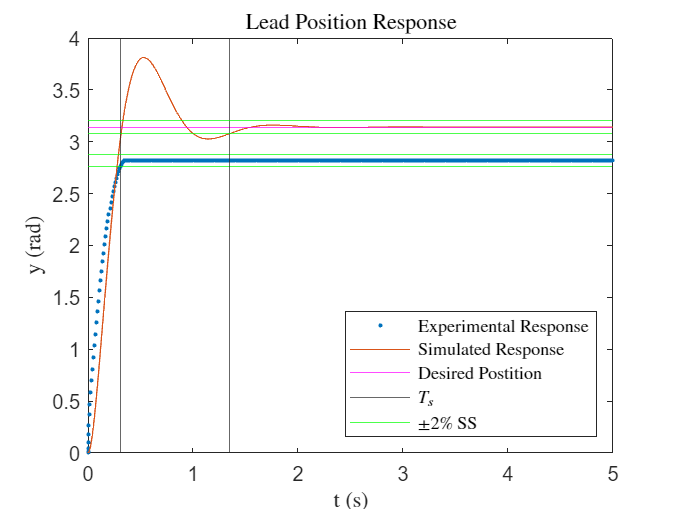

% plot position
plot(t, pos, '.')
hold on 
plot(out.Y.Time, out.Y.Data)
yline(r, 'm')
xline(T_s)
yline(F_v * 0.98, 'g')
yline(F_v * 1.02, 'g')
xline(T_s_sim)
yline(r * 0.98, 'g')
yline(r * 1.02, 'g')
hold off
title("Lead Position Response", 'Interpreter','latex')
xlabel('t (s)', 'Interpreter','latex')
ylabel('y (rad)', 'Interpreter','latex')
legend({"Experimental Response", "Simulated Response", "Desired Postition", '$T_s$', '$\pm{2\%}$ SS'},'Interpreter','latex', 'Location','southeast') 

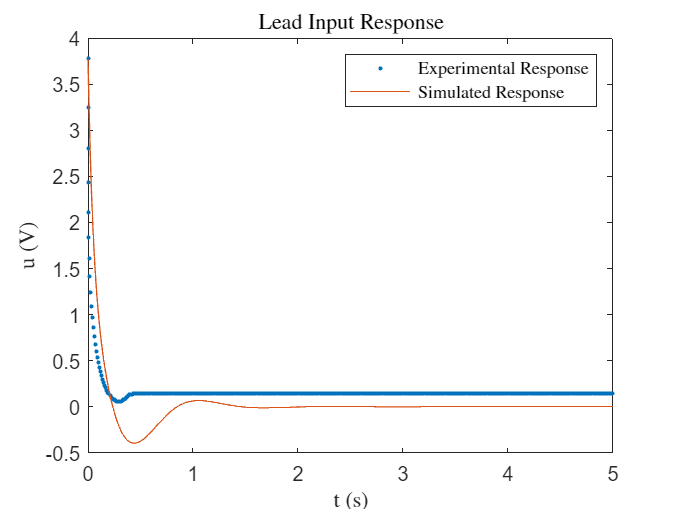


% plot input voltage
plot(t, inpt, '.')
hold on 
plot(out.u.Time, out.u.Data)
hold off
title("Lead Input Response", 'Interpreter','latex')
xlabel('t (s)', 'Interpreter','latex')
ylabel('u (V)','Interpreter','latex')
legend({"Experimental Response", "Simulated Response"},'Interpreter','latex', 'Location','northeast') 

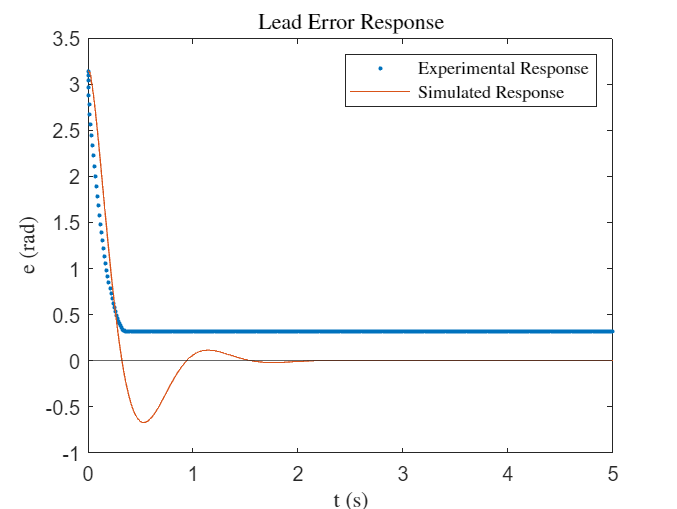


% plot error response
plot(t, error, '.')
hold on
plot(out.e.Time, out.e.Data)
yline(0)
hold off
title("Lead Error Response", 'Interpreter','latex')
xlabel('t (s)', 'Interpreter','latex')
ylabel('e (rad)', 'Interpreter','latex')
legend({"Experimental Response", "Simulated Response"},'Interpreter','latex', 'Location','northeast') 